Data Extraction from the Excel

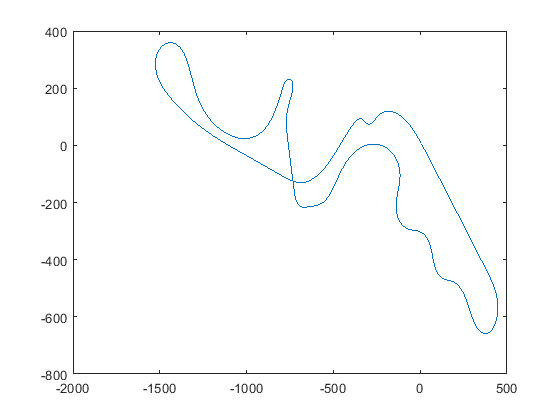

clear;
sanboks_data = xlsread('C:\Users\rk\Desktop\yash\New folder\SANBOKS 0.1\SANBOKS\Spreadsheets\Setup_F1_SUZUKA.xlsx');
[g, h] = size(sanboks_data);
track = sanboks_data(24:g,12:13);
track=rmmissing(track);
motor = sanboks_data(24:g,3:9);
gear_ratio =sanboks_data(9,9) ;
tire_radius = sanboks_data(7,4);
final_drivetrain_efficiency = sanboks_data(10,9);
car_mass = sanboks_data(1,4);
coefficient_rolling_resistance = sanboks_data(8,4);
frontal_area = sanboks_data(7,13);
drag_coefficient = sanboks_data(9,13);
lift_coefficient = sanboks_data(8,13);
aero_balance = sanboks_data(10,13);
grade_of_track = 0;
no_of_motors = sanboks_data(7,9);
min_radius=sanboks_data(16,9);
front_braking_torque = sanboks_data(16,4);
Rear_braking_torque = sanboks_data(17,4);
no_laps=sanboks_data(1,13);
start_time_for_peak=sanboks_data(8,9);
x= track(:,1)/1000;
y= track(:,2)/1000;
long_friction = sanboks_data(9,4);
lat_friction = sanboks_data(10,4);
rear_weight_distribution = sanboks_data(1,9);
steering_ratio = sanboks_data(16,13);
plot(x,y);

Extracting data from motor

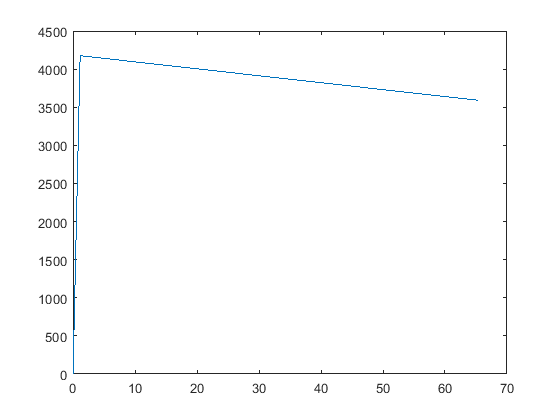

air_density = 1.12;
gravity = 9.81;
%%
peak_rpm = motor(:,4);
peak_torque = motor(:,3);
conti_rpm = motor(:,7);
conti_torque = motor(:,6);
current = motor(:,1);

%%
%removing the NaN from the data.
peak_rpm = rmmissing(peak_rpm);
peak_torque = rmmissing(peak_torque);
conti_rpm = rmmissing(conti_rpm);
conti_torque = rmmissing(conti_torque);
current = rmmissing(current);
%%
% PID value
peak_PID_increment = 1/(length(peak_rpm)-1);
conti_PID_increment = 1/(length(conti_rpm)-1);
peak_PID = 0:peak_PID_increment:1;
conti_PID = 0:conti_PID_increment:1;

plot(peak_torque,peak_rpm);

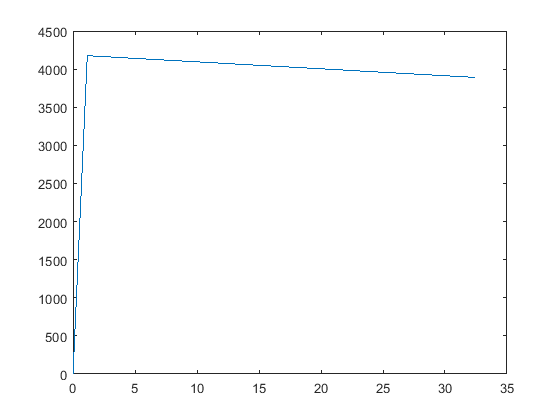

plot(conti_torque,conti_rpm);

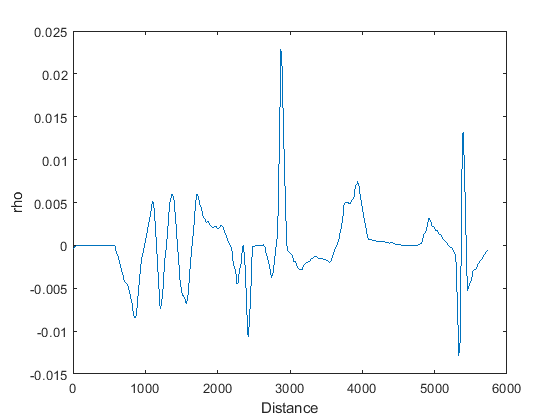

max_speed = min ((max(conti_rpm)*2*pi()*tire_radius)/(60*gear_ratio),((final_drivetrain_efficiency*max(conti_rpm)*max(conti_torque)*2*pi()/60)/(air_density*drag_coefficient*frontal_area))^(1/3));
max_speed = 92;
%%
x_leng=length(x);
for i = 1:x_leng
 if i == x_leng
 delta_x(i) = -x(1)+ x(i);
 delta_y(i) = -y(1)+ y(i);
 else
 delta_x(i) = x(i+1)- x(i);
 delta_y(i) = y(i+1)- y(i);
 end
end
track_length=0;
for i = 1:x_leng
 phia(i)=atan(delta_y(i)/delta_x(i));
 s(i)=sqrt(power((delta_x(i)),2)+power((delta_y(i)),2));
 if i == 1
 distance(i)=0+s(i);
 else
 distance(i)=distance(i-1)+s(i);
 end
 track_length=track_length+s(i);
end
j=1;
for i = 1:2:x_leng
    if i==x_leng
       delta_phia(j)= phia(1)-phia(i);
       delta_X(j)= delta_x(1)+delta_x(i);
       delta_Y(j)= delta_y(1)+delta_y(i);
       j=j+1;  
    else
    delta_phia(j)= phia(i+1)-phia(i);
    delta_X(j)= delta_x(i+1)+delta_x(i);
    delta_Y(j)= delta_y(i+1)+delta_y(i);
    j=j+1;
    end
end
delta_s = sqrt(power((delta_X),2)+power((delta_Y),2));
j=1;
delta_s_leng = length(delta_s);
for j = 1:delta_s_leng
 rho(j) = delta_phia(j)/delta_s(j);
end
%%
 points_filter(1)=0;
j=1;
for i = 1:delta_s_leng
    if rho(i)>=1/min_radius || rho(i)<=-1/min_radius
        points_filter(j)=i;
        j=j+1;
  
    end
end
%%
%filter
if points_filter(1)>0
for i=1:length(points_filter)
    if points_filter(i)==1
        rho(points_filter(i))=(rho(length(rho))+rho(points_filter(i)+1))/2;
    elseif points_filter(i)== length(rho)
    rho(points_filter(i))=(rho(points_filter(i)-1)+rho(1))/2;
    else
    rho(points_filter(i))=(rho(points_filter(i)-1)+rho(points_filter(i)+1))/2;
    end
end
 for i = 1:length(rho)
    if i==1
        if abs(rho(length(rho))- rho(i+1))<abs(rho(length(rho))-rho(i)) || abs(rho(length(rho))- rho(i+1))<abs(rho(i+1)-rho(i))
            rho(i)=(rho(length(rho))+rho(i+1))/2;
        end
    elseif i==length(rho)
        if abs(rho(i-1)-rho(1))<abs(rho(i-1)-rho(i)) || abs(rho(i-1)-rho(1))<abs(rho(1)-rho(i))
            rho(i)=(rho(i-1)+rho(1))/2;
        end
    else
        if abs(rho(i-1)-rho(i+1))< abs(rho(i-1)-rho(i)) || abs(rho(i-1)-rho(i+1))< abs(rho(i+1)-rho(i))
            rho(i)=(rho(i-1)+rho(i+1))/2;
        end
    end
end
end


%%
for i = 1:delta_s_leng
 velocity(i)= min(max_speed,sqrt(lat_friction*gravity/abs(rho(i))));
end

 plot(distance(1:2:x_leng), rho(1:delta_s_leng));
 xlabel('Distance');
 ylabel('rho');

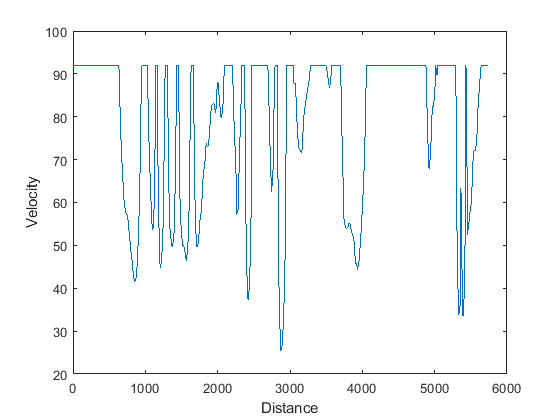


 plot(distance(1:2:x_leng), velocity(1:delta_s_leng));
 xlabel('Distance');
 ylabel('Velocity');

minimas = islocalmin(velocity);
%%
if points_filter(1)>0
j=1;
for i = 1:delta_s_leng
    if minimas(i)== 1
      corners(j) = i;
      j=j+1;
    end
end
%%
number_of_corner=length(corners);
c=1;
l=0;
for i=1:inf
    l=l+c;
    f=number_of_corner-l+1;
    k=corners(f);
    deaccelerate_velocity(k)= velocity(k);
    c=1;
    if f == 1
        for j=k:-1:2
            a_brk_max(j-1) = (long_friction*(car_mass*gravity+0.5*air_density*lift_coefficient*frontal_area* deaccelerate_velocity(j)^2+0.5*frontal_area*air_density*drag_coefficient*deaccelerate_velocity(j)^2))/car_mass;
            a_lat_max(j-1) = (lat_friction*(car_mass*gravity+0.5*air_density*lift_coefficient*frontal_area* deaccelerate_velocity(j)^2))/car_mass;
            a_lat(j-1) = min(a_lat_max(j-1),(deaccelerate_velocity(j)^2*abs(rho(j))));
            a_brk(j-1) = sqrt((1-(a_lat(j-1)/a_lat_max(j-1))^2))*a_brk_max(j-1);
            deaccelerate_velocity(j-1)=sqrt(deaccelerate_velocity(j)^2+2*a_brk(j-1)*delta_s(j));
        end
    else
        for j=k:-1:2
            a_brk_max(j-1) = (long_friction*(car_mass*gravity+0.5*air_density*lift_coefficient*frontal_area* deaccelerate_velocity(j)^2)+0.5*frontal_area*air_density*drag_coefficient*deaccelerate_velocity(j)^2)/car_mass;
            a_lat_max(j-1) = (lat_friction*(car_mass*gravity+0.5*air_density*lift_coefficient*frontal_area* deaccelerate_velocity(j)^2))/car_mass;
            a_lat(j-1) = min(a_lat_max(j-1),(deaccelerate_velocity(j)^2*abs(rho(j))));
            a_brk(j-1) = sqrt((1-(a_lat(j-1)/a_lat_max(j-1))^2))*a_brk_max(j-1);
           deaccelerate_velocity(j-1)= sqrt(deaccelerate_velocity(j)^2+2*a_brk(j-1)*delta_s(j));
          if  f-c >= 1
           if j-1 == corners(f-c)
             if deaccelerate_velocity(j-1) > velocity(corners(f-c))
                 break;
             end 
             c=c+1;  
           end
          else
              break;
          end
        end
    end
  if f-c<1
        break;
  end  
 if k == corners(1)
        break;
 end    

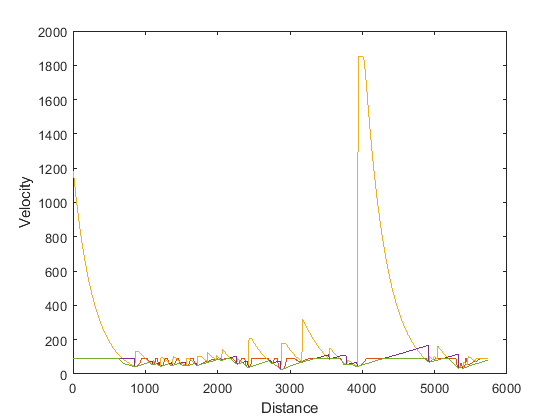

end
if length(deaccelerate_velocity)<delta_s_leng
    for k=length(deaccelerate_velocity)+1:delta_s_leng
        deaccelerate_velocity(k)=max_speed;
    end
end
for i = corners(number_of_corner)+1: delta_s_leng-1
    deaccelerate_velocity(i)=max_speed; 
end

plot(distance(1:2:x_leng),velocity);
plot(distance(1:2:x_leng),deaccelerate_velocity);
%%
c=1;
l=0;
for i= 1:inf
    l=l+c;
    f=l;
    k=corners(f);
    accelerate_velocity(k)= velocity(k);
    c=1;
    if f == number_of_corner 
     for j=k:delta_s_leng-1
           a_acc_max(j) = (long_friction*(car_mass*rear_weight_distribution*gravity+0.5*aero_balance*frontal_area*air_density*lift_coefficient* accelerate_velocity(j-1)^2)-0.5*frontal_area*air_density*drag_coefficient*accelerate_velocity(j-1)^2)/car_mass;
           a_lat_max(j) = (lat_friction*(car_mass*gravity+0.5*air_density*lift_coefficient*frontal_area* accelerate_velocity(j-1)^2))/car_mass;
           a_lat(j) = min(a_lat_max(j-1),(accelerate_velocity(j)^2*abs(rho(j))));
           a_acc(j) = sqrt((1-(a_lat(j)/a_lat_max(j))^2))*a_acc_max(j);
%         if((max(peak_torque)*gravity)/(tire_radius*car_mass)<a_acc(j))
%             a_acc(j)=(max(peak_torque)*gravity)/(tire_radius*car_mass);
%         end
           accelerate_velocity(j+1)=sqrt((accelerate_velocity(j)^2+2*a_acc(j)*delta_s(j)));
     end
    else 
        for j=k:delta_s_leng-1
           a_acc_max(j) = (long_friction*(car_mass*rear_weight_distribution*gravity+0.5*aero_balance*frontal_area*air_density*lift_coefficient* accelerate_velocity(j)^2)-0.5*frontal_area*air_density*drag_coefficient*accelerate_velocity(j)^2)/car_mass;
           a_lat_max(j) = (lat_friction*(car_mass*gravity+0.5*air_density*lift_coefficient*frontal_area* accelerate_velocity(j)^2))/car_mass;
           a_lat(j) = min(a_lat_max(j-1),accelerate_velocity(j)^2*abs(rho(j)));
           a_acc(j) = sqrt((1-(a_lat(j)/a_lat_max(j))^2))*a_acc_max(j);
%         if((max(peak_torque)*gravity)/(tire_radius*car_mass)<a_acc(j))
%             a_acc(j)=(max(peak_torque)*gravity)/(tire_radius*car_mass);
%         end
           accelerate_velocity(j+1)=sqrt((accelerate_velocity(j)^2)+2*a_acc(j)*delta_s(j));
        
           if  f+c <= number_of_corner
              if j+1 == corners(f+c)
               if accelerate_velocity(j+1) > velocity(corners(f+c))
                  break; 
               end
               c=c+1;
              end
           else
               if j>=delta_s_leng-1
%                for j=k:delta_s_leng-1
%            accelerate_velocity(j+1)=sqrt(power(accelerate_velocity(j),2)+2*max_acceleration*(distance(j+1)-distance(j)));
%                end
            
               break;
               end
           end
         
        end
    end
    if f+c>number_of_corner
        break;
    end
     if k == corners(number_of_corner)
        break;
    end    
end
for i = 1:length(accelerate_velocity)
    if accelerate_velocity(i)==0
        accelerate_velocity(i)=max_speed;
    end
end

plot(distance(1:2:x_leng),velocity);
plot(distance(1:2:x_leng),accelerate_velocity);

  
%%

plot(distance(1:2:x_leng),velocity);
plot(distance(1:2:x_leng),deaccelerate_velocity);
plot(distance(1:2:x_leng),accelerate_velocity);
    
xlabel('Distance');
ylabel('Velocity');
legend('Velocity','Deaccelerate Velocity','Accelerate Velocity');

%%
 after_deaccelaration_velocity=min(velocity,deaccelerate_velocity);
 achievable_velocity=min(after_deaccelaration_velocity,accelerate_velocity);
  plot(distance(1:2:x_leng),achievable_velocity);
 xlabel('Distance');
 ylabel('Velocity');

else
 achievable_velocity=velocity;    
 plot(distance(1:2:x_leng),achievable_velocity);
 xlabel('Distance');
 ylabel('Velocity');

end
hold on
plot(distance(1:2:x_leng),velocity);
plot(distance(1:2:x_leng),deaccelerate_velocity);
plot(distance(1:2:x_leng),accelerate_velocity);
plot(distance(1:2:x_leng),achievable_velocity);
    
xlabel('Distance');
ylabel('Velocity');
hold off

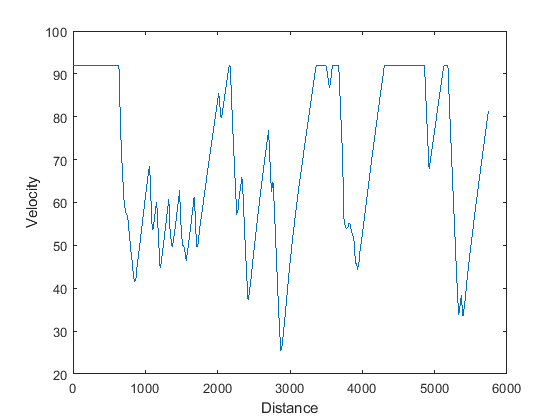


plot(distance(1:2:x_leng),achievable_velocity);
xlabel('Distance');
ylabel('Velocity');

for i=1:delta_s_leng
    if i == delta_s_leng
        time(i) = 2*(delta_s(i))/(achievable_velocity(1)+achievable_velocity(i));
    else
        time(i) = 2*(delta_s(i))/(achievable_velocity(i+1)+achievable_velocity(i));
    end
end
laptime = sum(time);
delta_s_track = sum(delta_s);

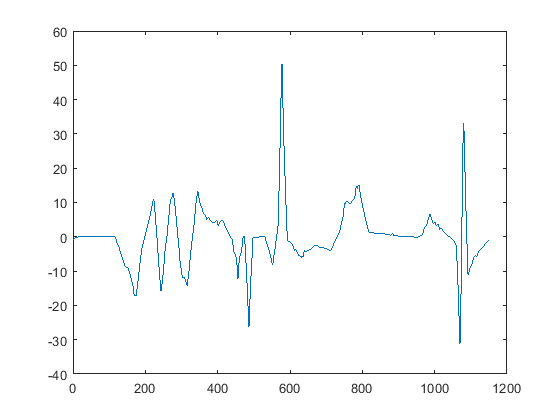

%%
for i=1:x_leng
   if i == 1
    vehicle_angle(i) = phia(1)-phia(x_leng);
   else
    vehicle_angle(i) = phia(i)-phia(i-1);
   end
end
reference_steering_angle = vehicle_angle*steering_ratio*180/pi;
for i=1:x_leng
    if reference_steering_angle(i)>180 || reference_steering_angle(i)<-180
        if i ==1
            reference_steering_angle(i)=(reference_steering_angle(x_leng)+reference_steering_angle(i+1))/2;
        elseif i == x_leng
            reference_steering_angle(i)=(reference_steering_angle(x_leng-1)+reference_steering_angle(1))/2;
        else
            reference_steering_angle(i)=(reference_steering_angle(i-1)+reference_steering_angle(i+1))/2;
        end
    end
end    
plot(reference_steering_angle);

sim('C:\Users\rk\Desktop\yash\New folder\SANBOKS 0.1\SANBOKS\Sanboks_LAP_sim.slx',2400);

Error due to multiple causes.

Caused by:
    Error using Sanboks_Script_V0_2 (line 351)
    Invalid setting in 'Sanboks_LAP_sim/1-D Lookup Table' for parameter 'BreakpointsForDimension1'.
        Error using Sanboks_Script_V0_2 (

open_system('C:\Users\rk\Desktop\yash\New folder\SANBOKS 0.1\SANBOKS\Sanboks_LAP_sim.slx');